clear all

% 480P videos / behavior file / DLC labels
video_to_load = './behaviorVids/Do20220225.mp4';

datfile = './shrewData.mat';

dlcvideo_meta = VideoReader(video_to_load);
max_frame = dlcvideo_meta.NumFrames;

for curr_tr=1:10000%max_frame
    dlcvideo(:,:,:,curr_tr) = readFrame(dlcvideo_meta);
end

max_frame = size(dlcvideo,4);
disp(['loading video ',num2str(i),' complete'])

% this function uses filtering and image segmentation with user input to
% define two masks for the right and left stimuli on the screen
[target_list_right,target_list_left,RightMask,LeftMask,yn_flip] = define_mask(dlcvideo);

% this function uses the masks to extract and normalize stimulus intensity
% and thresholds intensity to identify the on/offset of each trial
% might need to add option for iteratively adjusting threshold? currently
% adjusted manually
int_th = -0.2;
[right_on,left_on] = getTrialFrames(dlcvideo,RightMask,LeftMask,int_th);


img_idx = 3;
figure();
tiledlayout('TileSpacing','compact');
for ii = 1:length(right_on{img_idx})
    nexttile;
    imshow(dlcvideo(:,:,:,right_on{img_idx}(ii)));
end

% use average of each stimulus over trial to correlate with all target and
% distractor images to identify best match for both stimuli. outputs target
% ID and target side (1=right,0=left) for each trial
refimage=imread('target_0.png');
[imageID,camel_side] = correlateStim_autoit(dlcvideo,right_on,left_on,RightMask,LeftMask,refimage,target_list_left,target_list_right,yn_flip);


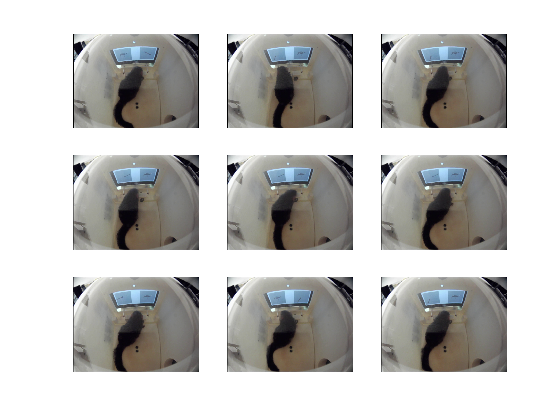

imgID = 0;
trIdx = find(imageID==imgID);
figure();
tiledlayout('TileSpacing','compact');
for ii = 1:sum(imageID==0)
    trial = trIdx(ii);
    nexttile;
    imshow(dlcvideo(:,:,:,right_on{trial}(round(end/2))));
    avgFrame(:,:,:,ii) = dlcvideo(:,:,:,right_on{trial}(round(end/2)));
end

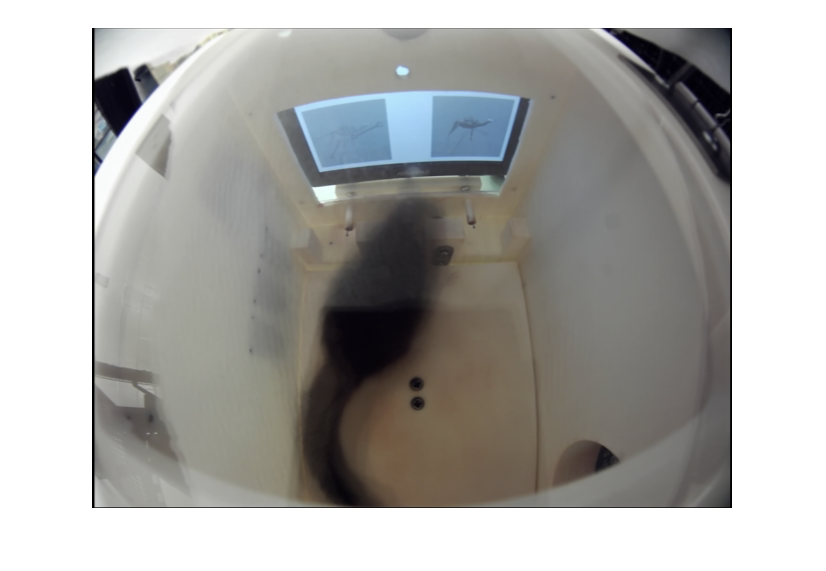

posAvg = mean(avgFrame,4);
figure();
imshow(uint8(posAvg))